# ***LDPC***

# `Soft Decision Decoding`

%%Getting information about the preloaded matrix H
%% or enter the H matrix here
H = [1 0 0 0 0 1 0 1 0 1 0 0;
 1 0 0 1 1 0 0 0 0 0 1 0;
 0 1 0 0 1 0 1 0 1 0 0 0;
 0 0 1 0 0 1 0 0 0 0 1 1;
 0 0 1 0 0 0 1 1 0 0 0 1;
 0 1 0 0 1 0 0 0 1 0 1 0;
 1 0 0 1 0 0 1 0 0 1 0 0;
 0 1 0 0 0 1 0 1 0 1 0 0;
 0 0 1 1 0 0 0 0 1 0 0 1];

%columns 
col = length(H);
%rows
row = height(H);
%degree of checknodes
dc = getdc(H);
%degree of variable nodes 
dv = getdv(H);
%connections of the checknodes
map_of_CN = getCNmap(dc,H);
%connections of the variable nodes 
map_of_VN = getVNmap(dv,H);

map_of_CN is matrix with dimensions - dc*row.  It stores the information of each checknode columnwise. For example,   map_of_CN(2,3) = 6 depicts that checknode 3 is connected with variable node 6.

map_of_VN is matrix with dimensions - dv*col.  It stores the information of each variablenode columnwise. For example,   map_of_VN(1,6) = 3 depicts that variablenode 6 is connected with check node 3.


%transmitted message
transmit_msg = zeros(1,col);

%number of simulations
Nsim = 10000;

%number of iterations 
max_it = 50;
no_of_it = 1:1:max_it;

%probability of successful decoding for different values of p
pbec = 0:0.1:1;
successProb = zeros(size(pbec));
index=1;



**Aim**:- For different values of bit erasure probability(*p*) we are estimating the probability of successful decoding.

**Procedure**: - -For each value of bit erasure probability we are repeating the same experiment for Nsim times(Monte-Carlo Simulation).

Experiment:- 

1. For given transmitted message and p, we add noise to the received message.

2.  Perform LDPC Decoding with *max_it* iterations.

3. Check if the message has correctly been decoded. 

Keep count of the number of times message was successfully decoded out of Nsim experiments.

 - The probability of successful decoding for given *p *will be Success count/Nsim.

-Repeat this for different values of p.


for p = pbec
    count_success = 0;
        for L = 1:1:Nsim
           
            
            received_msg = get_off_bec(transmit_msg,p,col);    %-------- 1.
            % Defining maps
            currMsg = received_msg;
            sentfromCN = zeros(size(map_of_CN));             %2_1) Contains information that each CN is sending to each VN in a particular iteration
            receivedtoVN = zeros(size(map_of_VN));           %2_2) Contains the same information of 2_1 but stored in different format--
                                                             %     contains what each VN received.
                                                             %     For example:- sentfromCN(2,3)= -1 <=> receivedtoVN(1,6)= -1 
                                                             %                   {assuming map_of_CN(2,3) = 6; map_of_VN(1,6)=3}
            
                                                             
            sentfromVN = zeros(size(map_of_VN));            %2_3) Contains information that each VN is senfing to each CN in a particular iteration
            receivedtoCN = zeros(size(map_of_CN));          %2_4) Contains the same information of 3_1 but stored in a different format--
                                                            %     contains what each CN received.
                                                            %     For example:- sentfromVN(1,6)= 0 <=> receivedtoCN(2,3)= 0 
                                                            %                   {assuming map_of_CN(2,3) = 6; map_of_VN(1,6)=3}

                                                   
            %---2. LDPC Decoding
                                               

            for it = 1:1:max_it
                
                prevMsg = currMsg;
    
                if it==1
                    sentfromCN = spc0(received_msg,map_of_CN);   
                else
                    sentfromVN =  repititioncode(receivedtoVN, received_msg,map_of_VN);
                    receivedtoCN = CNreceival(sentfromVN,map_of_VN,map_of_CN);
                    sentfromCN = spc(receivedtoCN, map_of_CN);
                end
    
                receivedtoVN = VNreceival(sentfromCN,map_of_CN,map_of_VN);
    
                currMsg = repetitioncodeforcurrmsg(receivedtoVN,received_msg);

                if(prevMsg==currMsg)
                    break;
                end

            end
            


The original message sent is assumed to be an all 0 message. Hence, the currMsg will be vector of 0s and -1(erasures) its sum its sum will be 0 only when all the elements are 0.

Note: In BEC, a variable node has only the correct value or an erasure i.e, 0 in transmitted message will never be interpreted as 1 in BEC.        

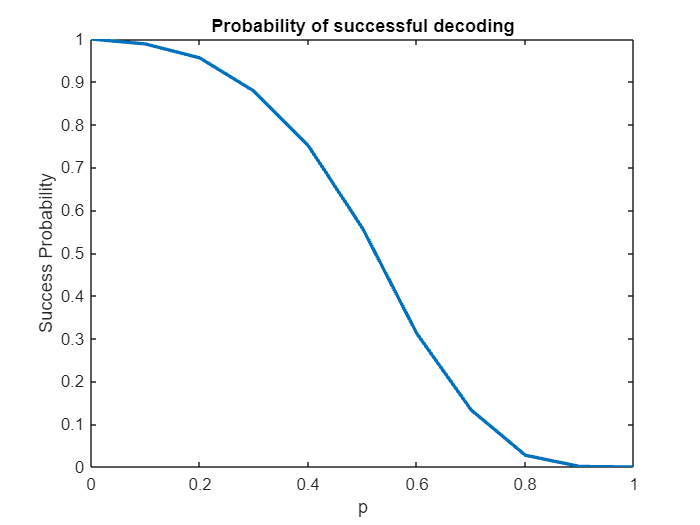

            %---3. Checking if the message is successfully decoded
            if sum(currMsg) == 0             
                count_success = count_success + 1;
            end
             
        end

        successProb(1,index) = count_success/Nsim;
        index=index+1;
end

figure;
plot(pbec,successProb,LineWidth=2);
xlabel('p');
ylabel('Success Probability');
title('Probability of successful decoding');

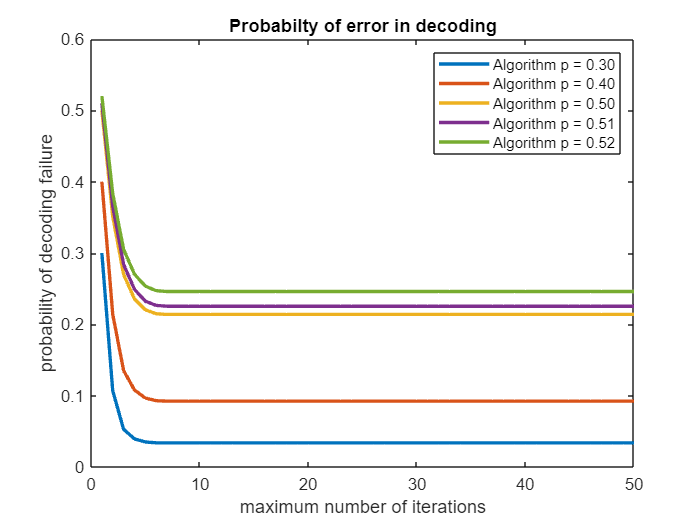


%Probability of error in decoding with respect to iterations
ps = [0.3, 0.4, 0.5, 0.51, 0.52];

for p = ps
    error = zeros(1,max_it);
        
        count = 0;
        count_error = 0;
    for L = 1:1:Nsim
       
        received_msg = get_off_bec(transmit_msg,p,col);
        currMsg = received_msg;
        sentfromCN = zeros(size(map_of_CN));
        receivedtoVN = zeros(size(map_of_VN));
        sentfromVN = zeros(size(map_of_VN));
        receivedtoCN = zeros(size(map_of_CN));
        error(1)=p*Nsim;
        for it = 1:1:max_it
            prevMsg = currMsg;

            if it==1

                sentfromCN = spc0(received_msg,map_of_CN);
                
            else
                
                sentfromVN =  repititioncode(receivedtoVN, received_msg,map_of_VN);
                receivedtoCN = CNreceival(sentfromVN,map_of_VN,map_of_CN);
                sentfromCN = spc(receivedtoCN, map_of_CN);
                                    
            end

            receivedtoVN = VNreceival(sentfromCN,map_of_CN,map_of_VN);

            currMsg = repetitioncodeforcurrmsg(receivedtoVN,received_msg);
               
            decoded = zeros(1,length(received_msg));
            erasure=0;
            for i=1:length(currMsg)
                if (currMsg(i)~=0 && received_msg(i)==1)
                    erasure=erasure+1;
                end
            end
           
            if it==max_it
                break;
            end
            error(it+1)  = error(it+1) + ((erasure)/length(currMsg)); 

        end             
            
    end
    error = error./Nsim;
    plot(no_of_it,error,'DisplayName',sprintf('Algorithm p = %.2f',p),LineWidth=2);
    hold on;
      
    
end
legend('show');
title('Probabilty of error in decoding');
xlabel('maximum number of iterations');
ylabel('probability of decoding failure');

function dc = getdc(H)
    dc = 0;
    row = height(H);
    col = length(H);
    for i = 1:row
        tmp = 0;
        for j = 1:col
            if H(i,j) == 1
                tmp = tmp+1;
            end
        end
        if dc<tmp
            dc = tmp;
        end
    end
end

function dv = getdv(H)
    row = height(H);
    col = length(H);
    dv = 0;
    for i = 1:col
        tmp = 0;
        for j = 1:row
            if H(j,i) == 1
                tmp = tmp+1;
            end
        end
        if dv<tmp
            dv = tmp;
        end
    end
end

%cn1 --> vn1, vn2...      map_of_CN(2,3) = 4 => CN 3 is connected to VN 4
function map_of_CN = getCNmap(dc,H)   
    row = height(H);
    col = length(H);
    map_of_CN = zeros(dc,row);
    for i = 1:row
        new_i = 1;
        for j=1:col
            if H(i,j) == 1
                map_of_CN(new_i,i) = j;
                new_i = new_i + 1;
            end
        end
    end
end

%vn1 --> cn1, cn2, ...   map_of_VN(2,4) = 3 => VN 4 is connected to CN 3
function map_of_VN = getVNmap(dv,H)   
    row = height(H);
    col = length(H);
    map_of_VN = zeros(dv,col);
    for i = 1:col
        new_i = 1;
        for j=1:row
            if H(j,i) == 1
                map_of_VN(new_i,i) = j;
                new_i = new_i + 1;
            end
        end
    end
end


function received_msg = get_off_bec(transmit_msg,p,col)
    received_msg = zeros(1,col);
    becNoise = rand(1,col)<p;
    %making the random message with bec error p
    for i = 1:col
        
        if becNoise(i) == 1
            received_msg(i) = 1;
%         elseif transmit_msg(i) == 1
%             received_msg(i) = 99;
        elseif transmit_msg(i) == 0
            received_msg(i) = 0;
        end
    end
end

%{
function check = checkerasure(msg)
    len = length(msg);
    check = 0;
    for i = 1:len
        if msg(i) == -1
            check = 1;
            break;
        end
    end
end
%}

function ansu = spc0(received_msg,map_of_CN)
      
    ansu = zeros(size(map_of_CN));
    [row, col] = size(map_of_CN);

    for i =1:1:col
        
        for j = 1:1:row
            sa = zeros(1,row-1);
            it = 1;
            
            for k = 1:1:row
                if k~=j
                    sa(it) = received_msg(map_of_CN(k,i))/(1+received_msg(map_of_CN(k,i)));
                    it = it + 1;
                end
            end
            
            

            if mod(row - 1,2) == 1
                p_1 = (sa(1)*(1-sa(2))*(1-sa(3))) + (sa(2)*(1-sa(1))*(1-sa(3))) +...
                    (sa(3)*(1-sa(2))*(1-sa(1))) + (sa(1)*(sa(2))*(sa(3)));
            else
                p_1 = (sa(1)*(1-sa(2))*(1-sa(3))*(1-sa(4))) + ...
                    (sa(2)*(1-sa(1))*(1-sa(3))*(1-sa(4))) +...
                    (sa(3)*(1-sa(2))*(1-sa(1))*(1-sa(4))) + ...
                    (sa(4)*(1-sa(2))*(1-sa(3))*(1-sa(1))) + ...
                    ((sa(1))*(sa(2))*(sa(3))*(1-sa(4))) + ...
                    ((sa(1))*(sa(2))*(1 - sa(3))*(sa(4))) + ...
                    ((sa(1))*(1 - sa(2))*(sa(3))*(sa(4))) + ...
                    ((1 - sa(1))*(sa(2))*(sa(3))*(sa(4)));
            end


            ansu(j,i) = p_1 / (1-p_1);

        end
    end


end

function ansu = VNreceival(sentfromCN,map_of_CN,map_of_VN)

    ansu = size(map_of_VN);
    [row, col] = size(map_of_CN);
    

    iterators = ones(1,length(map_of_VN));
    for i = 1:1:col
        for j = 1:1:row
            
            ansu(iterators(1,map_of_CN(j,i)), map_of_CN(j,i)) = sentfromCN(j,i);
            iterators(1,map_of_CN(j,i)) = iterators(1,map_of_CN(j,i))+1;
            

        end
    end


end

function ansu = repetitioncodeforcurrmsg(receivedtoVN,received_msg)

    ansu = zeros(1,length(received_msg));
    
    [row, col] = size(receivedtoVN);

    for i = 1:1:col

        value = received_msg(1,i);
        
        for j = 1:1:row
            
            value = value*receivedtoVN(j,i);    

        end

        ansu(1,i) = value;
        
    end

end


%sent from VN 

function ansu = repititioncode(receivedtoVN, received_msg,map_of_VN)

    ansu = zeros(size(map_of_VN));
    [row, col] = size(ansu);
    
    for i = 1:col
        for j = 1:row
            ansu(j,i) = received_msg(1,i);
            
            for k = 1:row
                if k ~= j 
                
                    ansu(j,i) = ansu(j,i)*receivedtoVN(k,i);

                end
            end
  
        end
    end

end


%received to CN calculations 
function ansu = CNreceival(sentfromVN,map_of_VN,map_of_CN)
    
    ansu = zeros(size(map_of_CN));

    iterators = ones(1,length(map_of_CN));

    [row,col] = size(sentfromVN);

    for i=1:col
        for j = 1:row
            ansu(iterators(1,map_of_VN(j,i)),map_of_VN(j,i)) = sentfromVN(j,i);
            iterators(1,map_of_VN(j,i)) = iterators(1,map_of_VN(j,i)) + 1;
        end
    end

end


%spc1 

function ansu = spc(receivedtoCN, map_of_CN)
    
    ansu = zeros(size(map_of_CN));
    
    [row,col] = size(receivedtoCN);
    
    for i = 1:col
        for j = 1:row
            sa = zeros(1,row-1);
            it = 1;
            for k = 1:row 
                if k ~= j 
                    sa(1,it) = receivedtoCN(k,i)/(1+receivedtoCN(k,i));
                    it = it + 1;
                end
            
            end
            if mod(row - 1,2) == 1
                p_1 = (sa(1)*(1-sa(2))*(1-sa(3))) + (sa(2)*(1-sa(1))*(1-sa(3))) +...
                    (sa(3)*(1-sa(2))*(1-sa(1))) + (sa(1)*(sa(2))*(sa(3)));
            else
                p_1 = (sa(1)*(1-sa(2))*(1-sa(3))*(1-sa(4))) + ...
                    (sa(2)*(1-sa(1))*(1-sa(3))*(1-sa(4))) +...
                    (sa(3)*(1-sa(2))*(1-sa(1))*(1-sa(4))) + ...
                    (sa(4)*(1-sa(2))*(1-sa(3))*(1-sa(1))) + ...
                    ((sa(1))*(sa(2))*(sa(3))*(1-sa(4))) + ...
                    ((sa(1))*(sa(2))*(1 - sa(3))*(sa(4))) + ...
                    ((sa(1))*(1 - sa(2))*(sa(3))*(sa(4))) + ...
                    ((1 - sa(1))*(sa(2))*(sa(3))*(sa(4)));
            end
            ansu(j,i) = p_1/(1-p_1);
        
        end
    end

end
